% Data from [Mesh data structure selection for mesh generation and FEA applications]
% Memory storage
mem_element = [25 25 25 25 25 25 6 6 18 18]';
mem_connect = [143 93 129 119 142 128 43 77 115 129]';
mem_total = mem_element + mem_connect;

% Operation count
% F(R) E(R) V (R) R(F) E(F) V (F) R(E) F(E) V (E) R(V ) F(V ) E(V )
ope = [4 36 30 2 3 13 50 5 2 619 399 14
    4 36 30 211 3 13 512 877 2 23 1394 1749
    4 36 30 2 3 13 297 252 2 360 35 840
    4 36 30 48 3 13 5 210 2 339 1710 14
    4 36 30 211 3 13 512 252 2 23 35 14
    4 36 30 211 3 13 512 252 2 23 35 840
    72 58 4 302 24 3 214 721 2 23 3462 1969
    84 58 4 2 24 3 214 731 2 23 3532 84
    4 58 21 2 24 3 267 251 2 360 35 1449
    4 58 21 2 24 3 267 251 2 360 35 84];

% DSC references
    name_ref = ['F(R)'; 'E(R)'; 'V(R)'; 'R(F)'; 'E(F)'; ...
        'V(F)'; 'R(E)'; 'F(E)'; 'V(E)'; 'R(V)'; 'F(V)'; 'E(V)'];
dsc_ref = [192 5 100 105 265 187 1 59 800 7 3 73]';

% Their reference
mega_ref = [73 23 429 543 8121 185 1 950 12006 27 48 2102]';


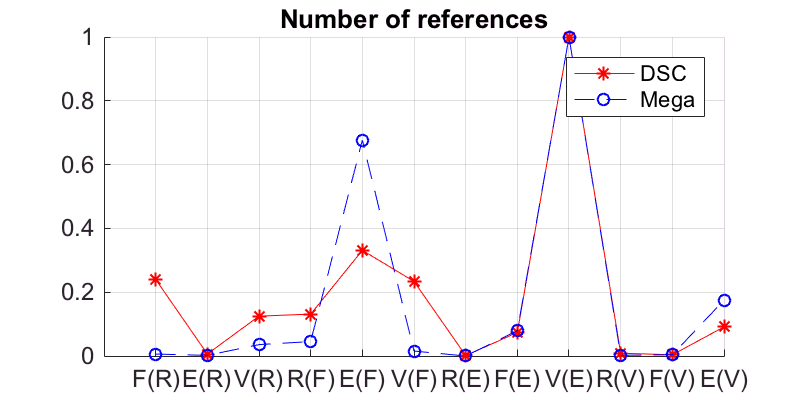

t = table((name_ref), dsc_ref, mega_ref, ...
    'VariableNames',{'Refs' 'DSC' 'Mega'});

hh1=figure; hold on;
plot(dsc_ref/max(dsc_ref), 'r*-');
plot(mega_ref/max(mega_ref), 'bo--');
hold off;
title('Number of references');legend('DSC', 'Mega');
ax = gca;ax.XTickLabel = name_ref;tt=1:12; ax.XTick=tt;
set(hh1, 'Position', [100, 100, 400, 200]);
grid on;

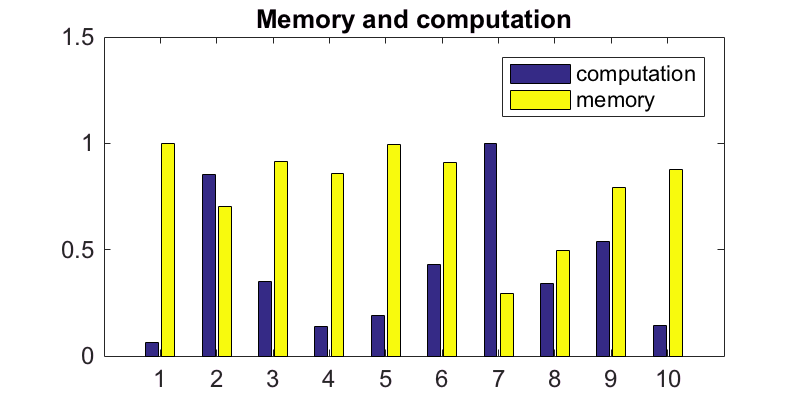

% Computation
% average operation
ope_total = ope * dsc_ref;

ope_total_scale = ope_total / max(ope_total);
mem_total_scale = mem_total / max(mem_total);
name_method = {'1.F1, one level, DSC', '2.F2 circular tet-node', ...
    '3.F3, cicular faces-vertices', '4.F4, circular tet-edge', ...
    '5.F5, 2 circualr', '6.F6, reduce 2 circular'...
    '7.R1, compact', '8.R2, flex', '9.R3, mid', '10.R4, mid flex'};

hh2 = figure;
bar([ope_total_scale mem_total_scale]);

title('Memory and computation');
ylim([0, 1.5]); xlim([0,11]);
set(hh2, 'Position', [100, 100, 400, 200]);
legend({'computation'; 'memory'});


index = 1:10;
disp(table(index', name_method', 'VariableNames', {'index' 'Method'}));

    index                Method            
    _____    ______________________________
     1       '1.F1, one level, DSC'        
     2       '2.F2 circular tet-node'      
     3       '3.F3, cicular faces-vertices'
     4       '4.F4, circular tet-edge'     
     5       '5.F5, 2 circualr'            
     6       '6.F6, reduce 2 circular'     
     7       '7.R1, compact'               
     8       '8.R2, flex'                  
     9       '9.R3, mid'                   
    10       '10.R4, mid flex'             


% DSC operation cost
index = 1:12;
t1 = table(index', categorical(name_ref), ope(1,:)', dsc_ref, ...
    'VariableNames',{'index' 'Refs' 'operations' 'reference'});

disp(t1);

    index    Refs    operations    reference
    _____    ____    __________    _________
     1       F(R)      4           192      
     2       E(R)     36             5      
     3       V(R)     30           100      
     4       R(F)      2           105      
     5       E(F)      3           265      
     6       V(F)     13           187      
     7       R(E)     50             1      
     8       F(E)      5            59      
     9       V(E)      2           800      
    10       R(V)    619             7      
    11       F(V)    399             3      
    12       E(V)     14            73      


fileID = fopen('test.txt');
C = textscan(fileID,'%s %s %s %s %s %s %s %s %s');
fclose(fileID);
celldisp(C)

C{1}{1} =
edge
C{1}{2} =
edge
C{1}{3} =
edge
C{1}{4} =
face
C{1}{5} =
face
C{1}{6} =
node
C{1}{7} =
node
C{1}{8} =
node
C{1}{9} =
tet
C{1}{10} =
tet
C{2}{1} =
-
C{2}{2} =
-
C{2}{3} =
-
C{2}{4} =
-
C{2}{5} =
-
C{2}{6} =
-
C{2}{7} =
-
C{2}{8} =
-
C{2}{9} =
-
C{2}{10} =
-
C{3}{1} =
face:
C{3}{2} =
nodes:
C{3}{3} =
tet:
C{3}{4} =
edge:
C{3}{5} =
tete:
C{3}{6} =
edge:
C{3}{7} =
face:
C{3}{8} =
tet:
C{3}{9} =
edge:
C{3}{10} =
face:
C{4}{1} =
1.437209
C{4}{2} =
0.331041
C{4}{3} =
0.434997
C{4}{4} =
0.175580
C{4}{5} =
0.425794
C{4}{6} =
2.311838
C{4}{7} =
7.665400
C{4}{8} =
7.703598
C{4}{9} =
0.068442
C{4}{10} =
0.269192
C{5}{1} =
in
C{5}{2} =
in
C{5}{3} =
in
C{5}{4} =
in
C{5}{5} =
in
C{5}{6} =
in
C{5}{7} =
in
C{5}{8} =
in
C{5}{9} =
in
C{5}{10} =
in
C{6}{1} =
2785130
C{6}{2} =
761896
C{6}{3} =
56741
C{6}{4} =
455558
C{6}{5} =
832477
C{6}{6} =
5281282
C{6}{7} =
1856816
C{6}{8} =
689783
C{6}{9} =
6380
C{6}{10} =
439534
C{7}{1} =
iters;
C{7}{2} =
iters;
C{7}{3} =
iters;
C{7}{4} =
iters;
C{7}{5} =